# Ingenuity

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

The Ingenuity copter is a small autonomous helicopter that made history as the first powered, controlled flight on another planet, Mars. Its design is the result of a collaboration between the Jet Propulsion Laboratory (JPL) and NASA. This project was part of the Mars 2020 mission and was deployed on Mars by the Perseverance rover. On April 19th, 2021, it was the first helicopter to perform a controlled flight in the thin atmosphere of Mars. Since then, it completed a series of complex flights paving the way for future aerial exploration of other planets.

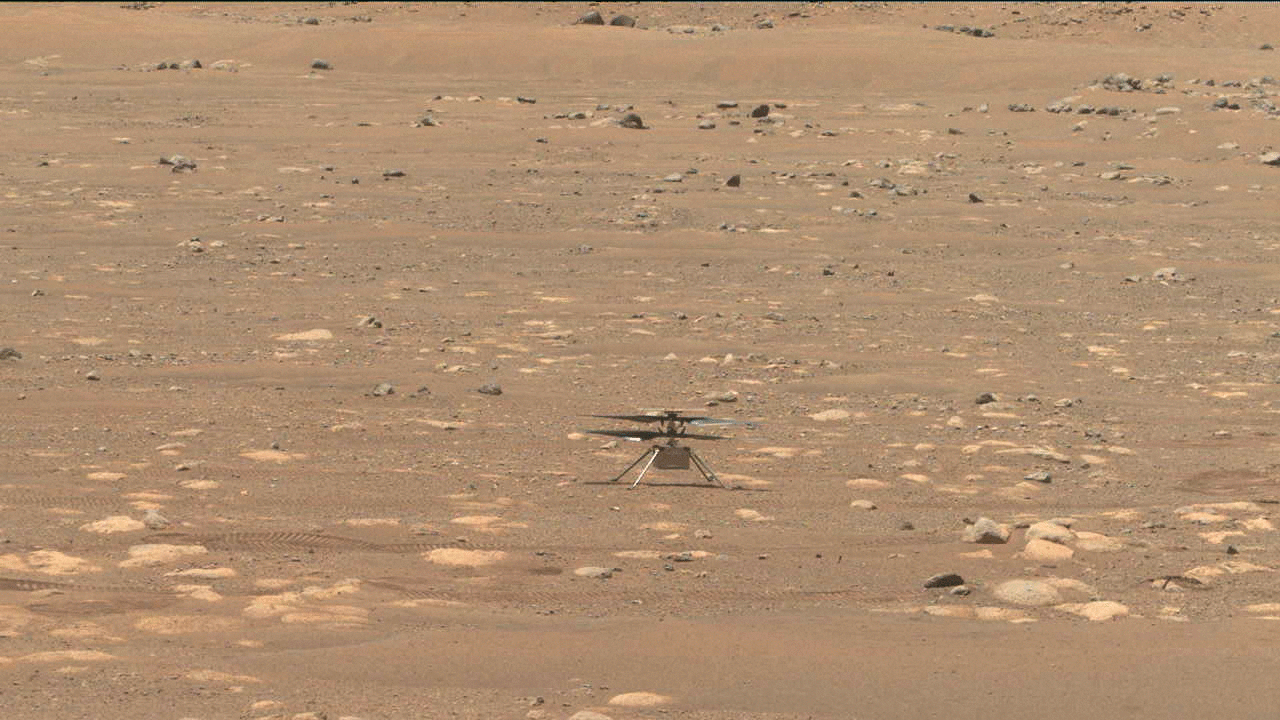

Ingenuity copter blades start to spin, credit: [NASA/JPL-Caltech/ASU](https://www.jpl.nasa.gov/missions/ingenuity)

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. 

The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

Dimensional analysis is a powerful mathematical tool that allows engineers to study the consistency of physical equations, derive relationships between physical quantities, and reduce the number of variables that are involved in a problem. It allows us to identify parameters that control physical systems and to express complex relationships between those parameters using dimensionless numbers. This method is used in engineering, physics, and other sciences to solve problems involving complex physical systems and it has many practical applications.

### Units and dimensions

 **Definition.** Dimensions are physical quantities that can be measured. Every dimension can be defined based on a combination of fundamental dimensions: the mass $M$, time $T$, length $L$, electric current $I$, temperature $\Theta$, amount of substance $N$ and the luminous intensity $J$. For example, velocity is a physical quantity that can be measured, and its dimension can be expressed as $L\cdot T^{-1}$.

 **Defintion.** Units are arbitrary quantities that can be measured and correspond to a precise measurement of a dimension. For example, one mole is a unit of amount of substance $N$ used in the International System of Units (SI) that corresponds to $6.022\cdot 10^{23}$ elementary entities (such as atoms or molecules).

  **Try. **Every dimension can be measured using many different units.

 
unitInfo("Length")


All units of dimension 'Length':

Ao - angstrom
au - astronomical unit
a_0 - Bohr radius
ch - chain
ft - foot
ftm - fathom
ft_US - U.S. survey foot
fur - furlong
gg - gauge
hand - hand
in - inch
inm - international nautical mile
land - league
li - link
line - line
ly - light-year
m - meter ['SI']
mi - mile
mil - mil
mi_US - U.S. survey mile
nmile - British imperial nautical mile
pc - parsec
pica - pica
pica_US - U.S. customary pica
pt - point
pt_US - U.S. customary point
rod - rod
span - span
xu - x unit
xu_Cu - x unit (copper)
xu_Mo - x unit (molybdenum)
yd - yard

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



While the unit system is often different based on the local tradition and the technical field, in this script we are going to use the international system of units for all our measurement and calculation.

  **Try. **Define the base unit system.

 
SIunits = baseUnits('SI')

$$SIunits = \left(\begin{array}{ccccccc} \mathrm{kg} & s & m & A & \mathrm{cd} & \mathrm{mol} & K \end{array}\right)$$

## Ingenuity's design

### Identify the physical variables

Ingenuity is a small helicopter deployed on planet Mars with the Perseverance rover. It was design by JPL (Jet Propulsion Laboratory). The helicopter wingspan $D$ is 1.2 m, its mass $m$ is 1.6 kg, Mars' atmosphere is defined by its density $\rho$ and viscosity $\mu$, while the acceleration due to the gravitational force is $g$, $\omega$ is the angular velocity of the rotor, and the thrust from the propeller is $F_T$.

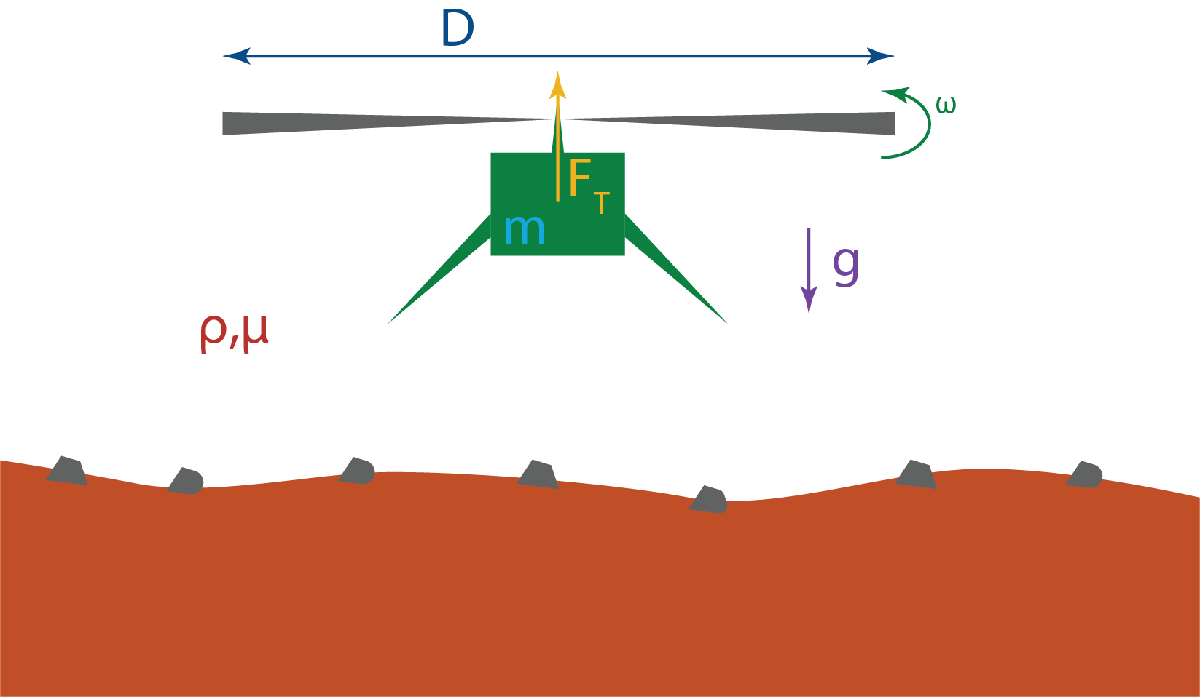

The thrust force of the helicopter can be fitted as a function of all other variable:


$$f(F,\rho,g,\omega,m,D) = 0$$


A naive approach would be to characterize the helicopter by considering all six parameters $(\rho,g,\omega,m,D,F)$. This could be done but would require numerous experiments, requiring too much time. Instead, we are going to perform a dimensional analysis to reduce the number of variables required to characterize the system.

In the rest of this script, we are going to write each measurement as a value and units such as:


$$\rho = \bar{\rho} \cdot [\text{units}]$$


The first step of the dimensional analysis is to identify the independent parameters and their fundamental dimension. 

  **Try. **Symbolicly define the density as $\rho=\bar\rho\cdot[\text{units of density}]$.

% Define the measurement:
syms rho_bar g_bar omega_bar m_bar D_bar
syms F_bar
% Define the unit system
u = symunit;

rho = rho_bar * (u.kg/u.m^3)

$$rho = \bar{\rho }\,\frac{\mathrm{kg}}{m^{3}}$$

 **Exercise. **Modify the following edit fields to add the units to the other parameters.

% Your code goes in the following edit fields:
g = g_bar * (1); 
omega = omega_bar * (1); 
m = m_bar * (1);
D = D_bar * (11);

% Define the lift force:
F = F_bar * u.N;
F = unitConvert(F,SIunits);

  CheckUnitsParameters(g,omega,m,D)

### Determine the number of fundamental dimension

Each measurement of the parameters is now associated in their units in the SI unit system. 

  **Try. **Modify the following edit field to add the units to the other parameters.

% Gather all the units together in a vector:
unitsUsed = findUnits([rho, g, omega, D, m, F])

$$unitsUsed = \left(\begin{array}{ccc} \mathrm{kg} & m & s \end{array}\right)$$

The Ingenuity design is composed of six variables; however these parameters only use three fundamental dimensions, the mass $M$, length $L$ and time $T$. 

### **Buckhingham-**$\pi$** theorem**

 **Definition.** A physical problem involving $n$ variables involving $p$ fundamental dimensions can be expressed as a function of $n-p$ dimensionless quantites.

In the case of the Ingenuity rover we have $n=6$ and $p=3$, therefore the helicopter can be characterized using $n-p=6-3=3$ dimensionless parameters.The Buckingham-$\pi$ theorem is gets its name from the Greek letter $\pi$ because the dimensionless numbers are commonly denoted using the letter $\pi$.

The problem:


$$f(F,\rho,g,\omega,m,D) = 0$$


Can be rewritten as:


$$\phi(\pi_1,\pi_2,\pi_3) = 0$$


#### Select repeating variables

We are selecting repeating variables that will appear in $(\pi_1,\pi_2,\pi_3)$. These variables must have units, the units must be different, and every dimension must be covered by their units:

 **Exercise. **Select the repeating variable.

checkRepeatingVariable(...
    F,...
    F,...
    F);

#### Define dimension scale

Many combinations of repeating variables are possible and would lead to the same results. In the rest of the script, we are going to consider a single set of repeating variables: $[D,\omega,\rho]$. Now that we defined the repeating variables, we can express a characteristic scale for each of the fundamental dimensions involved in the problem.

  **Try. **Click on the following button to define the characteristic length scale.

 
L_scale = D

$$L\_scale = 11\,\bar{D}$$

 **Exercise. **Similarly, define the mass and time scales only using the repeating variables.

% Your code goes here"
M_scale = rho*D^3;
T_scale = 1/omega;

% Check answer:
 checkDimensionScale(M_scale,T_scale)

#### Scale the problem variables

We can now define the dimensionless group as a function of the non-repeating variables $[F,g,m]$ and the characteristic scale of the fundamental dimensions defined in the previous section.

  **Try. **Run the following section to define the dimensional scale for length.

 pi_1 = F / (1)

$$pi\_1 = \bar{F}\,\frac{\mathrm{kg}\,m}{s^{2}}$$

 **Reflect.** Notice that we can verify that it is a dimensionless number because there are no units showing in the results.

 **Exercise. **Reduce the other problem variables to their dimensionless form.

% Your code goes in the following edit fields:
pi_2 = g / (1)
pi_3 = m / (1)

% Check Answer:
  checkDiemensionalGroup(pi_2,pi_3)

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

$$pi\_2 = \bar{g}$$

### Experimental study

A prototype of the Ingenuity copter was tested on Earth. The helicopter mass was fixed to 1.6 $\text{kg}$, five different rotors were tested with radius $R = [1, 3, 10, 30, 100]$ $\text{cm}$. Five different rotor rotation speed were considered $\omega = [1,3,10,30,100]$ $\frac{\text{rad}}{\text{s}}$. The air density of the day of the experiment was 1.2 $\frac{\text{kg}}{\text{m}^3}$ and the local gravitational acceleration is considered equal to 9.81 $\frac{\text{m}}{\text{s}^2}$.

  **Try. **Load the experiment results.

 
load Ingenuity.mat

Error using load
Unable to find file or directory 'Ingenuity.mat'.

ExperimentResult

We can now compute the value of the dimensionless group for each experimental result.

  **Try. **Compute $\pi_1$ 

 

ExperimentResult.pi_1 = ExperimentResult.F./...
    ((2*ExperimentResult.R).^4.*ExperimentResult.Omega.^2.*ExperimentResult.Rho)

Recall that the variables you defined were

displayFormula(["'pi_1 = '" , string(pi_1), "'   and   '","'pi_2 = '", string(pi_2),"'   and   '", "'pi_3 = '", string(pi_3)])

 **Exercise. **Similarly**, **Compute the ratio $\pi_2$ and $\pi_3$ as defined in the previous section.

% Your code goes here:
ExperimentResult.pi_2(:) = 0;
ExperimentResult.pi_3(:) = 0;

% Check answer:
  checkPiExperiment(ExperimentResult)

### Design conclusion

The experimental results demonstrate that the first dimensionless ratio is constant:


$$\pi_1 = \frac{F}{D^4 \omega^2 \rho} = 0.0034$$


The engineering group settles on a rotor diameter of 1.2 $\text{m}$, the atmospheric density on Mars is 0.02 $\frac{\text{kg}}{\text{m}^3}$, the force required for take-off should be 10% greater than the gravitational force felt by the helicopter, the mass of Ingenuity is 1.8 $\text{kg}$ and the local acceleration due to gravity is 3.712 $\frac{\text{m}}{\text{s}^2}$.

  **Try. **Define the minimal rotor rotation speed to operate on Mars.

 

% Define the problem parameters:
syms F D omega rho
pi_1 = F/(D^4*omega^2*rho) == 0.0034
pi_1 = subs(pi_1, [F D rho], [1.1*3.712*1.8 1.2 0.02])
omega = solve(pi_1,omega,"PrincipalValue",true)*u.rad/u.s
omega = rewrite(omega,u.rpm)
omega = vpa(omega,5)

 **Reflect.** Compare the result from our analysis with the [Ingenuity specification](https://mars.nasa.gov/files/mars2020/MarsHelicopterIngenuity_FactSheet.pdf).

## Common dimensionless group

The head loss in the horizontal pipe flow can be expressed as a problem with six variables:


$$f(\Delta P, D, L, \rho,\mu,v) = 0$$


Where $\Delta P$ is the pressure drop, $D$ is the pipe diameter, $L$ is the pipe length, $\rho$ is the fluid density, $\mu$ is the fluid dynamic viscosity and $v$ is the velocity. 

syms D_bar v_bar rho_bar Delta_P_bar mu_bar L_bar
u = symunit;

D = D_bar * u.m;
v = v_bar * u.m/u.s;
rho = rho_bar * u.kg/u.m^3;
Delta_P = Delta_P_bar * u.Pa;
Delta_P = unitConvert(Delta_P,SIunits);
mu = mu_bar * u.kg/u.m/u.s;
L = L_bar * u.m;
unitsUsed = findUnits([D,v,rho,Delta_P,mu,L])

The number of variable is $n=6$ and the number of dimension is $p=3$, therefore we can define $n-p=3$ dimensionless ratio to characterize the problem. We select $D
$, $\rho$ and $v$ as repeating variables. The first dimensionless ratio is expressed in term of $L$:

pi_1 = L / D

The second dimensionless ratio is expressed in term of $\mu$:

pi_2 = mu / (rho*D*v)

We recognize that this ratio is equal to the inverse of the Reynolds number:


$$\text{Re} = \frac{\rho D v}{\mu}$$


In fact, this is where the Reynolds number come from. 

The third dimensionless ratio is expressed in term of $\Delta P$:

pi_3 = Delta_P / (rho*v^2)

We can rewritte the problem as:


$$\pi_3 = \phi(\pi_1,\pi_2)$$


Many dimensionless groupings are commonly used depending on the nature of the problem. When the Reynolds number is the most common one that you might encounter, you could find reference to the following dimensionless grouping:

- [Darcy friction factor:](matlab:open('./InternalFlow.mlx')) $\text{C}_\text{f}$

- Drag coefficient: $c_d = \frac{2F_d}{\rho v^2 A}$

- Euler number: $\text{Eu} = \frac{\Delta p}{\rho V^2}$

- Froude number: $\text{Fr} = \frac{g L^3}{\nu^2}$

- Mach number: $\text{Ma} = \frac{v}{c}$

- Peclet number: $\text{Pe} = \frac{Lu}{D}$

- Pressure coefficient: $C_p = \frac{p-p_\infty}{\frac{1}{2}\rho_\infty V_\infty^2}$

## Further exploration

The experimental data presented in this script were generated using the new [rotor blockset](https://www.mathworks.com/help/releases/R2023a/aeroblks/rotor.html) in Simulink. The block itself uses dimensionless number to simulate the lift generated by a rotor: the lift $(C_L)$ and torque coefficient $(C_Q)$. 

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

## Helper Functions

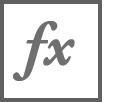`CheckUnitsParameters(answerA,answerB,answerC,answerD)`

function CheckUnitsParameters(answerA,answerB,answerC,answerD)
    arguments
        answerA (1,1) sym
        answerB (1,1) sym
        answerC (1,1) sym
        answerD (1,1) sym
    end

    % Define the error flag and the unit system
    ierr = 0;
    u = symunit;

    % check all the units
    if ~checkUnits(answerA == u.m/u.s^2,'Consistent')
        if checkUnits(answerA == u.m/u.s^2,'Compatible')
            warning("The gravitational acceleration unit is not consistent with the SI"+...
                " units system, try expressing it in meter per second square.")
        else
            warning("The gravitational acceleration unit is not compatible with the"+...
                " dimension of acceleration.")
        end
        ierr = ierr + 1;
    end
    if ~checkUnits(answerB == 1/u.s,'Consistent')
        if checkUnits(answerB == 1/u.s,'Compatible')
            warning("The rotor angular velocity is not consistent with the SI units system,"+...
                " try expressing it in radian per second.")
        else
            warning("The rotor angular velocity unit is not compatible with the dimension of"+...
                " angular velocity.")
        end
        ierr = ierr + 1;
    end
    if ~checkUnits(answerC == u.kg,'Consistent')
        if checkUnits(answerC == u.kg,'Compatible')
            warning("The mass is not consistent with the SI units system, try "+...
                "expressing it in kg.")
        else
            warning("The mass unit is not compatible with the dimension of mass.")
        end
        ierr = ierr + 1;
    end
    if ~checkUnits(answerD == u.m,'Consistent')
        if checkUnits(answerD == u.m,'Compatible')
            warning("The rotor diameter is not consistent with the SI units system, try "+...
                "expressing it in m.")
        else
            warning("The rotor diameter unit is not compatible with the dimension of length.")
        end
        ierr = ierr + 1;
    end

    if ierr == 0
        disp("Good job! All of the units selected are correct.")
    end

end

`checkRepeatingVariable(answerA,answerB,answerC)`

function checkRepeatingVariable(answerA,answerB,answerC)
    arguments
        answerA (1,1) sym
        answerB (1,1) sym
        answerC (1,1) sym
    end
    answers = [answerA answerB answerC];
    [~,combinationUnits] = separateUnits(nchoosek(answers,2));
    ierr = 0;
    for i = 1:size(combinationUnits,1)
        if isequal(combinationUnits(i,1),combinationUnits(i,2))
            ierr = ierr + 1;
        end
    end
    if ierr ~= 0
        warning("At least two variables present the same dimensions.")
    end
    
    u = symunit;
    unitsUsed = sort(findUnits([answerA,answerB,answerC]));
    unitRequired = sort([u.m u.kg u.s]);
    if isequal(unitsUsed,unitRequired)
        if ierr == 0
            disp("Good job! You defined the repeating variable correctly.")
        end
    else
        warning("Your set of repeating variables does not cover every fundamental"+...
            " dimension involved in this problem.")
    end

end

`checkDimensionScale(answerA,answerB)`

function checkDimensionScale(answerA,answerB)
    arguments
        answerA (1,1) sym
        answerB (1,1) sym
    end

    syms rho_bar D_bar omega_bar
    u = symunit;
    rho = rho_bar * u.kg/u.m^3;
    D = D_bar * u.m;
    omega = omega_bar / u.s;

    rightAnswerA = rho*D^3;
    rightAnswerB = 1/omega;
    
    if isequal(answerA,rightAnswerA) && isequal(answerB,rightAnswerB)
        disp("Good job! The dimensional scales are defined correctly")
    else
        warning("At least one of the scales is wrong.")
    end

    % Add more feedback XXX
end

`checkDiemensionalGroup(answerA,answerB)`

function checkDiemensionalGroup(answerA,answerB)
    arguments   
        answerA (1,1) sym
        answerB (1,1) sym
    end
    
    syms g_bar D_bar omega_bar m_bar rho_bar
    rightAnswerA = g_bar/(D_bar*omega_bar^2);
    rightAnswerB = m_bar/(D_bar^3*rho_bar);

    if isequal(answerA,rightAnswerA) && isequal(answerB,rightAnswerB)
        disp("Good job! The dimensionless group is defined correctly.")
    else
        warning("At least one of the dimensionless group is wrong.")
    end

    % Add more feeback XXX

end

`checkPiExperiment(answer)`

function checkPiExperiment(answer)
    load IngenuitySoln.mat
    
    i2 = all(ExperimentResultSoln.pi_2 == answer.pi_2);
    i3 = all(ExperimentResultSoln.pi_3 == answer.pi_3);

    if ~i2
        warning("There is a problem in the calculation for pi_2.")
    end

    if ~i3
        warning("There is a problem in the calculation for pi_3.")
    end

    if i2 && i3
        disp("Good job! You computation of the dimensional groups is correct.")
    end

end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc